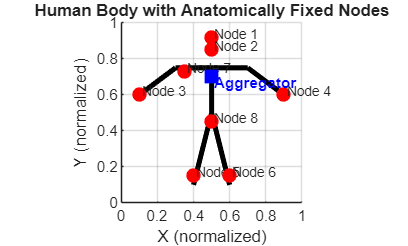

% Create output directory
outputDir = 'C:\Users\saidu\Documents\MATLAB\ComparisonPlots';
if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end

%% 1. Figure 1: Human Body with Anatomically Fixed Nodes

% Sensor node positions (normalized to [0,1])
nodePositions = [
    0.5, 0.92;   % Node 1 - Head for EDA
    0.5, 0.85;   % Node 2 - Neck for RR
    0.1, 0.6;    % Node 3 - Left wrist for HR
    0.9, 0.6;    % Node 4 - Right wrist for BP
    0.4, 0.15;   % Node 5 - Left knee for BVP
    0.6, 0.15;   % Node 6 - Right knee for SPO2
    0.35, 0.73;  % Node 7 - Left armpit for BT
    0.5, 0.45    % Node 8 - Lower abdomen for BS
];

aggregatorNode = [0.5, 0.7]; % Aggregator on chest

% Create figure
figure1 = figure;
hold on;
axis equal;
grid on;
set(gca, 'xtick', 0:0.2:1, 'ytick', 0:0.2:1);
xlim([0 1]);
ylim([0 1]);
title('Human Body with Anatomically Fixed Nodes', 'FontWeight', 'bold');

% Draw human body
rectangle('Position', [0.475, 0.89, 0.05, 0.05], 'Curvature', [1 1], 'FaceColor', [0.85 0.85 0.85]); % Head
plot([0.5, 0.5], [0.89, 0.86], 'k', 'LineWidth', 2); % Neck
plot([0.3, 0.7], [0.75, 0.75], 'k', 'LineWidth', 3); % Shoulders
plot([0.5, 0.5], [0.75, 0.5], 'k', 'LineWidth', 3); % Torso
plot([0.3, 0.1], [0.75, 0.6], 'k', 'LineWidth', 3); % Left arm
plot([0.7, 0.9], [0.75, 0.6], 'k', 'LineWidth', 3); % Right arm
plot([0.5, 0.4], [0.5, 0.1], 'k', 'LineWidth', 3); % Left leg
plot([0.5, 0.6], [0.5, 0.1], 'k', 'LineWidth', 3); % Right leg

% Plot sensor nodes
for i = 1:size(nodePositions, 1)
    plot(nodePositions(i,1), nodePositions(i,2), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
    text(nodePositions(i,1)+0.015, nodePositions(i,2)+0.015, sprintf('Node %d', i), 'FontSize', 8);
end

% Plot aggregator node
plot(aggregatorNode(1), aggregatorNode(2), 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
text(aggregatorNode(1)+0.015, aggregatorNode(2)-0.035, 'Aggregator', 'FontSize', 9, 'FontWeight', 'bold', 'Color', 'b');

xlabel('X (normalized)');
ylabel('Y (normalized)');

% Save Figure 1
saveas(figure1, fullfile(outputDir, 'Human_Body_with_Anatomically_Fixed_Nodes.png'));

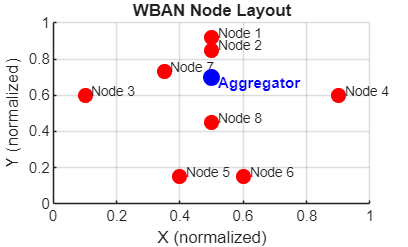


%% 2. Figure 2: WBAN Node Layout (Simple Plot)

figure2 = figure;
hold on;
grid on;
xlim([0 1]);
ylim([0 1]);
title('WBAN Node Layout', 'FontWeight', 'bold');
xlabel('X (normalized)');
ylabel('Y (normalized)');

% Plot sensor nodes
scatter(nodePositions(:,1), nodePositions(:,2), 80, 'r', 'filled');
text(nodePositions(:,1)+0.02, nodePositions(:,2)+0.02, ...
    arrayfun(@(n) sprintf('Node %d', n), 1:8, 'UniformOutput', false), 'FontSize', 8);

% Plot aggregator node
scatter(aggregatorNode(1), aggregatorNode(2), 100, 'b', 'filled');
text(aggregatorNode(1)+0.02, aggregatorNode(2)-0.03, 'Aggregator', 'FontSize', 9, 'FontWeight', 'bold', 'Color', 'b');

% Save Figure 2
saveas(figure2, fullfile(outputDir, 'WBAN_Node_Layout.png'));


fprintf('Both figures saved to:\n%s\n', outputDir);

Both figures saved to:
C:\Users\saidu\Documents\MATLAB\ComparisonPlots
